# Exercice #1 : Deriving Radar Specifications

clear;
clc;
format shortEng;

%---------------------------------------------------------------------------------------------------
% GOALS : 
% In this chapter, we will derive budget for TX, RX and antenna subsystems
% from a set of high level requirements
% We will use MATLAB and explore a few functions that will help use define
% SNR, transmit power, max. allowable noise figure (RX) as well as the antenna
% (array) gain.
%
% We will use the interactive Radar Designer App. to run a few more
% analysis and explore potential tradeoffs. Using and exploring
% capabilities provided by this interactive app will represent the largest
% part of this exercise.
%
% 
% After we will have derived those figures, we will implement a simulation
% model to verifiy the behavior. We will start with a very simple and high
% level model and will refine the subsystems in further exercices.
%
% NOTE : 
% This workshop's intent is not to show how to design a "state of the art"
% radar and our example will remain very simple so that we can focus on a
% proposed workflow.
%---------------------------------------------------------------------------------------------------

### High Level Requirements

We have received the following high-level requirements from our customer : 

- Radar should operate at a center frequency of **2.4 GHz**

- Should detect targets without ambiguities up to** 75 km**

- Should detect a** 10 square meters target** located at **35 km**

- Range resolution should be at least 150 m

- Antenna beamwidth should not exceed **10°x10**° and should be **steerable**

- Max. size for the antenna array should not exceed 50 x 50 cm

- **100W** per T/R module max.

- Waveform generator delivers 2mW (3dBm)

%---------------------------------------------------------------------------------------------------
% PART 1 : The Basics 
% Define physical constants (speed of light, Boltzmann's constant,
% wavelength, ...) from the available information 
%---------------------------------------------------------------------------------------------------

## Fundamental informations

- Physical constants

c       = physconst('LightSpeed');      % speed of light
k       = physconst('Boltzmann');       % Boltzmann's constant (compute noise power density)
T       = 290.0;                        % Temperature (expressed in Kelvin)

- Center frequency is imposed by our customer and regulation

fc = 2.4e9;     % center frequency

we will need to fill the wavelength in many equations or functions : $\lambda =\frac{c}{f}$

lambda  = freq2wavelen(fc,c)            % 

## Waveform Settings

In this exercise, we will use a "rectangular" waveform. We could explore gains offered by a modulated waveform (chirp, barker codes, ...) with MATLAB functions available in Radar toolbox.

- Max. unambiguous range = 75 km

This value allows us to define the pulse repetition interval to provide an unambiguous detection

maxUnambiguousRange    = 75e3;
PRI                    = range2time(maxUnambiguousRange,c)  % Pulse Repetition Interval
PRF                    = 1/PRI;                              % Pulse repetition Frequency

- Derive pulse width from required range resolution using the `rangeres2bw` function

rangeResolution     = 150.0;
requiredBandwidth   = round(rangeres2bw(rangeResolution, c),2,"significant");
pulseWidth          = 1/requiredBandwidth;
dutyCycle           = (pulseWidth/PRI)*100

### To go beyond...

We are using a rectangular waveform and our receiver will apply a matched filter to improve SNR for target detection. We will address this topic and implement this matched filter in our simulation model.

- [https://mathworks.com/help/phased/ug/matched-filtering.html](https://mathworks.com/help/phased/ug/matched-filtering.html)

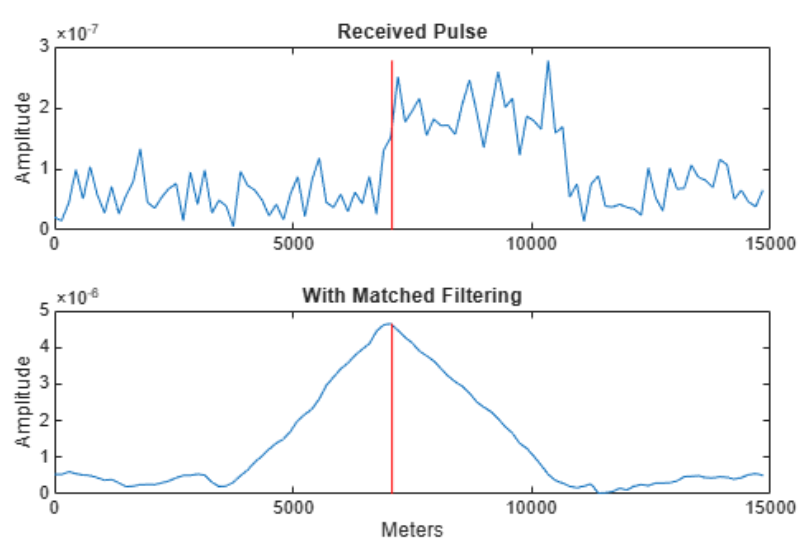

## Probability of Detection (Pd) and Probability of False Alarm (Pfa)

- What is the required SNR for a specified Probability of detection and probability of false alarm ?

%---------------------------------------------------------------------------------------------------
% EXERCISE
% Hint: use the 'rocpfa' function to calculate the required signal to noise
% ratio and probability of detection of the received signal to achieve a
% specified probability of false alarm.
% Type 'doc rocpfa' into the command line interface for more information.
%
% Visualize the Pd vs. SNR plot for Pfa values of 1e-7, 1e-6 and 1e-3 and
% for a non fluctuating target (swerling0) and a single pulse
% What is the required SNR for a probability of detection of 90% in each case ?
%---------------------------------------------------------------------------------------------------

% doc 'rocpfa'      % uncomment to view documentation

`Solution : `

- `illustrate how to use the yline`

- `illustrate how to interactively make measurements on the graph`

Pfa = [1e-7, 1e-6, 1e-3];

% ---- TODO -----
% your code here
% ----- --- -----

yline (0.9,'blue:')

- We know, by experience, that  `Pd =0.9` and `Pfa = 1e-6` will provide good detections for a typical radar.

- We also will integrate (non-coherently) 10 pulses

Pd  = 0.9;
Pfa = 1e-6;
N   = 10;

%---------------------------------------------------------------------------------------------------
% EXERCISE
%
% Hint: use the 'detectability' function to calculate the required signal to noise
% ratio for the specified Pd, Pfa and number of pulsed to integrate.
% Type 'doc detectability' into the command line interface for more information.
%
% Visualize the Pd vs. SNR plot for Pfa values of 1e-7, 1e-6 and 1e-3 and
% for a non fluctuating target (swerling0) and a single pulse
% What is the required SNR for a probability of detection of 90% in each case ?
%---------------------------------------------------------------------------------------------------

- `The ``detectability`` factor or ``required SNR, ``is the signal-to-noise ratio needed to detect a target with the desired probabilities of detection and false alarm.`

% doc detectability   % uncomment to open documentation page

`Solution : `

% ---- TODO -----
% snr = <your code here>
% ----- --- -----

### Radar Range equation

We will use the radar range equation, in different forms, to estimate the required TX power to achieve a specified SNR as well as compute the power received at target and the echo received on the radar RX antenna.

The next exercices will extensively use the radar equation. Please refer to this doc. page for more details:

- [https://mathworks.com/help/releases/R2025b/radar/ug/radar-equation.html](https://mathworks.com/help/releases/R2025b/radar/ug/radar-equation.html)

In our simulation model, we will verify the power levels at different stages and we wil recall the radar equation as follow : 

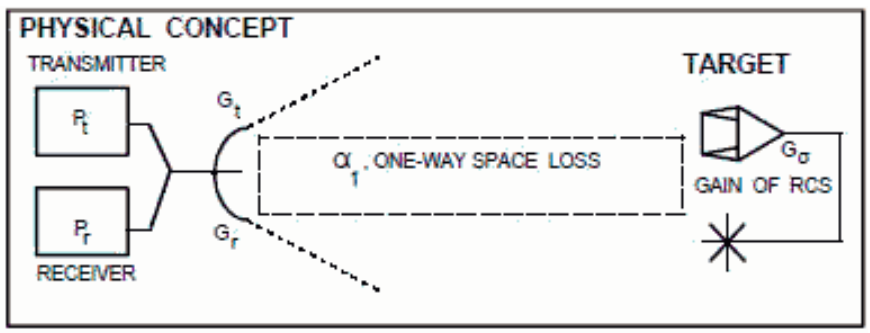


$$P_r =\frac{P_{t\;} x\;G_t }{4\pi R^2 }\;x\;\sigma \;x\;\frac{1}{4\pi R^2 }\;x\;A_e$$


Where : 

- Pr = received power

- Pt = Peak transmit power in watts

- Gt = Transmit/Receive antenna gain

- $\sigma =\;$target's nonfluctuating radar cross section in square meters

- R = range from radar to target

- Ae = effective aperture  = $\frac{G\lambda^2 }{4\pi }$

EIRP `(Effective Isotropic Radiated Power)`

- We now have a target `SNR` for a given `Pd` and `Pfa` and number of pulsed to integrate

- Let's derive the required `EIRP (`$\left.\textrm{EIRP}=\textrm{txPower}\;x\;\textrm{txAntennaGain}\right)$

targetRCS   = 10.0;         % radar cross section of target
refRange    = 35e3;         % Distance at which we want to detect the target with specified Pd and Pfa

%---------------------------------------------------------------------------------------------------
% EXERCISE
%
% Hint: use the 'radareqpow' function to calculate the required EIRP (ie.
% antenna gain = 0dBi) to detect a 10 sqm target at 40 km.
% Type 'doc radareqpow' into the command line interface for more information.
%
% Supply wavelength, target range, snr, pulse width, RCS, temperature and
% antenna gain (0dBi)
% Call the output EIRP
% Compute EIRP in dBW and name the variable EIRP_dBW
%---------------------------------------------------------------------------------------------------

% ---- TODO -----
% EIRP = <your code here>
% ----- --- -----
EIRP_dBW    = 10*log10(EIRP)

### Account for Antenna Gain

- We consider a monostatic radar in this exercise to that Tx antenna gain and Rx Antenna gain will be identical.

- We would like to get a rough estimate for the antenna gain we could achieve for a given beamwidth. Our customer's requirements mentionned antenna beamwidth should not exceed `10°x10°`.

- Our Antenna Design department mentionned we could reuse an existing design approaching a cosineRectangular aperture...

What is the typical antenna gain for a specific beamwidth ?

hpbw            = [10; 10];                                 % [az;el] degrees                                                  
antennaGaindBi   = beamwidth2gain(hpbw,'CosineRectangular')  % estimate antenna gain
antennaGain_lin = power(10,antennaGaindBi/10)

### TX Power

%---------------------------------------------------------------------------------------------------
% EXERCISE
% Now that we have an estimate of our antenna gain, let's run the
% radareqpow() again to get an estimate of the required TX power
% Call the output txPowerWatts
% Express the tx power in dBW
%---------------------------------------------------------------------------------------------------

% ---- TODO -----
% txPowerWatts = <your code here>
% ----- --- -----

txPowerdBW      = 10*log10(txPowerWatts)

%---------------------------------------------------------------------------------------------------
% SANITY CHECK
%---------------------------------------------------------------------------------------------------

- TX power expressed in dBW, should be the same as : 

EIRP_dBW - (2*antennaGaindBi)

% Optional 
% It may be interesting to get a feeling for the average power. When using
% a recytangular waveform, this value will be very low and could justify
% the usage of pulse compression techniques

%Pavg        = txPowerWatts*dutyCycle

### Sanity check

Let run the radareqsnr( ) function with the values we have just derived...just to make sure we get the expected SNR :

SNR = radareqsnr(lambda, ...
    refRange, ...
    txPowerWatts, ...
    pulseWidth,...
    RCS=targetRCS,...
    Ts=T,...
    Gain=antennaGaindBi)

## Experiment with radarDesigner App

%---------------------------------------------------------------------------------------------------
% EXERCISE
%
% We will now open the Radar Designer App, plug the values we have derived
% so far and experiment with different options to improve our design
%
%---------------------------------------------------------------------------------------------------

- [https://mathworks.com/help/radar/ref/radardesigner-app.html](https://mathworks.com/help/radar/ref/radardesigner-app.html)

- [https://mathworks.com/help/radar/ug/radar-design-part-I-from-power-budget-analysis-to-dynamic-scenario-simulation.html](https://mathworks.com/help/radar/ug/radar-design-part-I-from-power-budget-analysis-to-dynamic-scenario-simulation.html)

- Open the Radar Designer App

radarDesigner

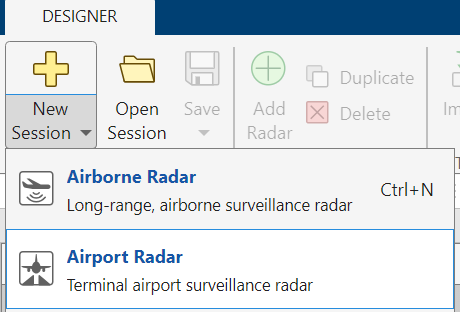

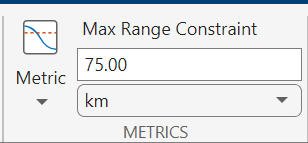

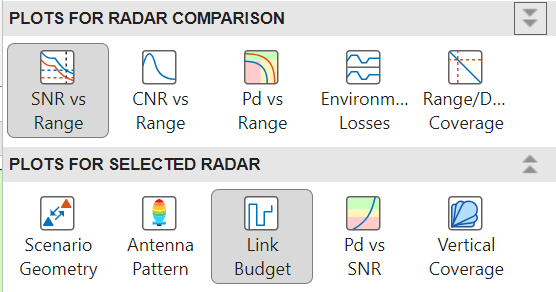

- Fill values in the different fields

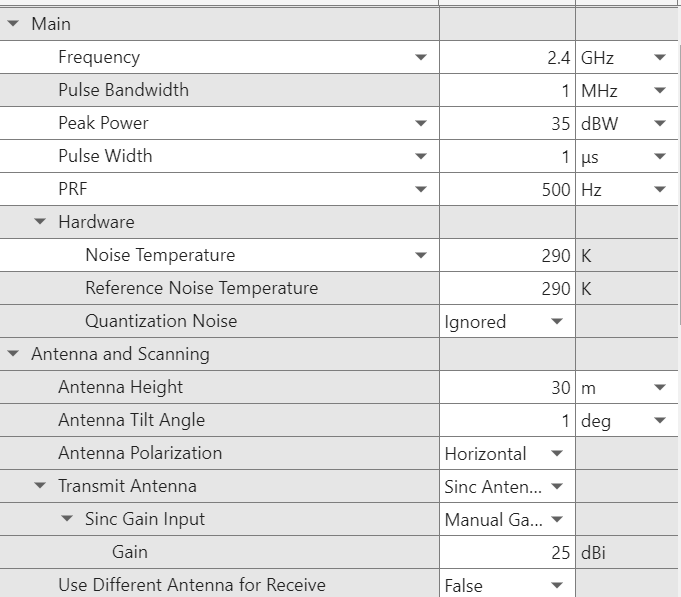

- Define threshold and objectice and observe the pass/fail fields :

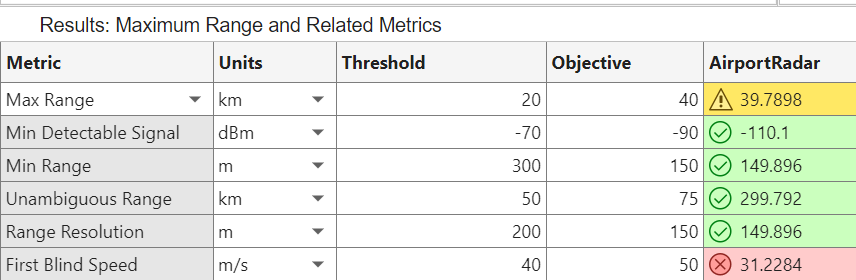

- Observe the metrics plots and discuss our design (will most likely not meet the specs as is...)

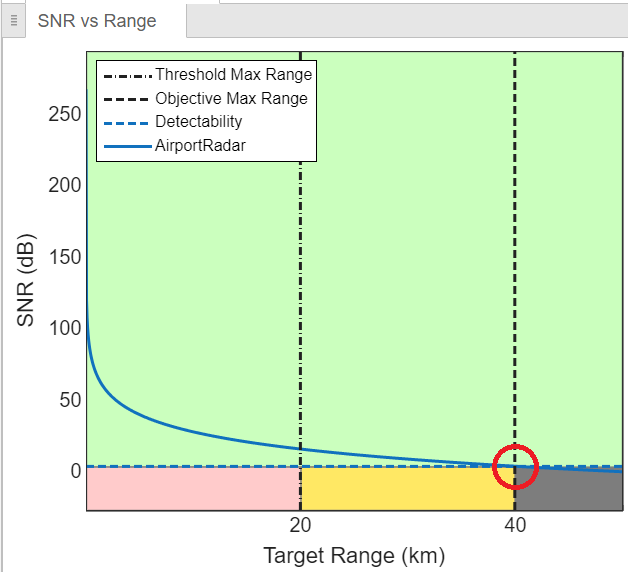

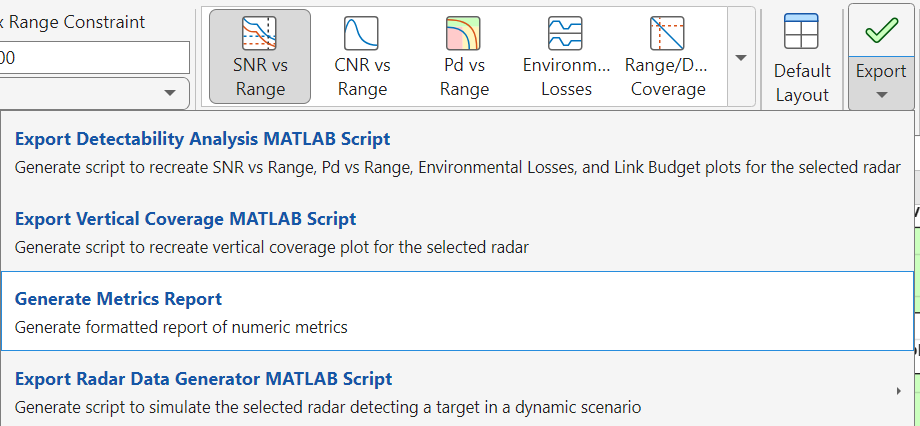

### Exploring RadarDesignerApp Plots and stoplight charts

- When to use ?

- Benefits ?

%---------------------------------------------------------------------------------------------------
% OPTIONAL
%---------------------------------------------------------------------------------------------------

### RECEIVER

We will recall the Radar Equation : $P_r =\frac{P_{t\;} \ldotp G_t }{4\pi R^2 }\;x\;\frac{\sigma }{4\pi R^2 }\;x\;A_e$ and will rewrite it in a slightly different (but equivalent) manner to allow us measure the values (dBW) at each stage of the simulation (vs. power densities that cannnot be measured directly).


$$P_r =P_{t\;} \ldotp G_t \;x\;\frac{\lambda^2 }{4\pi R^2 }\;x\;\frac{\sigma 4\pi }{\lambda^2 }\;x\;\frac{G_r \ldotp \lambda^2 }{4\pi R^2 }$$


- Let's compute the noise power at RX if NF = 0 dB (ie. a perfect RX that would bring any contribution to noise)

rxNF_dB     = 0.0;
rxNoise     = noisepow(requiredBandwidth,rxNF_dB,T);
rxNoise_dBW = 10*log10(rxNoise)

- Compute power reaching the RX using the radar equation :


$$P_r =\frac{P_{t\;} x\;G_t }{4\pi R^2 }\;x\;\frac{\sigma }{4\pi R^2 }\;x\;A_e$$


- Power density reaching the target


$$a=\frac{\left(\textrm{Pt}\ldotp \textrm{Gt}\right)}{4\ldotp \pi \ldotp {\mathrm{R}}^2 }$$


a       = (txPowerWatts*antennaGain_lin)/(4*pi*(refRange^2)); % W/m2
a_dBW   = 10*log10(a); % W/m2


$$b=\frac{\sigma }{4\ldotp \pi \ldotp {\mathrm{R}}^2 }$$


b       = targetRCS/(4*pi*(refRange^2));


$$c=\frac{G\lambda^2 }{4\pi }$$


c = (antennaGain_lin*(lambda^2))/(4*pi); % m2

rxSignal = a*b*c
signalToNoise   = rxSignal/rxNoise
snr_dB = 10*log10(signalToNoise)

-  In these conditions, our radar will not meet the specs. We do not have enough margin to build a robust solution and should increase txPower, antennaGain or number of pulses to integrate, or a combination of those.

- In addition, we are not considering realistic values for Noise Figure or Losses and our estimation is very optimistic and would most ikely lead to a non-working solution in the 'real-world'. 

**Conclusion** : We need to take more realistic parameters into account, losses due to the RF Front-End (non-linearities, noise figure, impedance mismatches, ...), environment (propagation over terrain, rain, gases, ...) and assess the credibility of the figures derived with emprirical formulas such as an accurate value for the antenna gain and its best-case/worst-case operating conditions (gain at boresigth vs. beam steering at a large angle).

[All models are wrong...but some are useful ](https://en.wikipedia.org/wiki/All_models_are_wrong)(George Box)

### Simulation Model

%---------------------------------------------------------------------------------------------------
% We will now explore a simulation model allowing us to verify our results
% This model is a very high level simulation created to verify the
% gains and other RF budgets elements in our design will meet the
% specifications and enable detections of a radar signal backscaterred from
% a target located at 35km.
%---------------------------------------------------------------------------------------------------

modelName = 'System_Level_Behavioral';
open_system(modelName)

### Going beyond...

- Radar Link Budget Analysis : [https://mathworks.com/help/radar/ug/radar-link-budget-analysis.html](https://mathworks.com/help/radar/ug/radar-link-budget-analysis.html)

- Radar Detectability factors : [https://mathworks.com/help/radar/ug/modeling-radar-detectability-factors.html](https://mathworks.com/help/radar/ug/modeling-radar-detectability-factors.html)

- Improve waveform design : [https://fr.mathworks.com/help/phased/ug/waveform-design-to-improve-performance-of-an-existing-radar-system.html](https://fr.mathworks.com/help/phased/ug/waveform-design-to-improve-performance-of-an-existing-radar-system.html)